# Overdetermined Linear Systems (HW06 hints)

Math 3607, Autumn 2021

Tae Eun Kim.3562

## Linear Least Squares: General Fitting Functions

t = (0:0.5:10)';
y = tanh(t);

(a) Polynomial fitting (cubic polynomial)

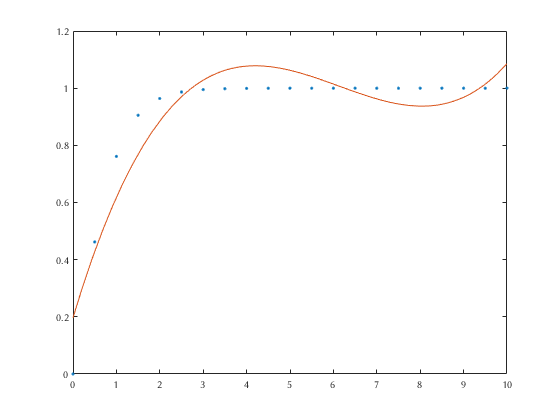

n = 4;    % cubic fitting function
V = t.^(0:n-1);
c = V\y;  % coeffs in descending
p = @(t) polyval(flip(c), t);

clf
plot(t, y, '.'), hold on
fplot(p, [0 10])

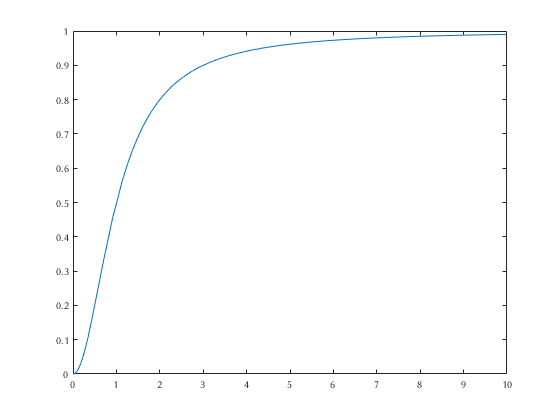

clf
fplot(zfun, [0 10])

(b) General fitting

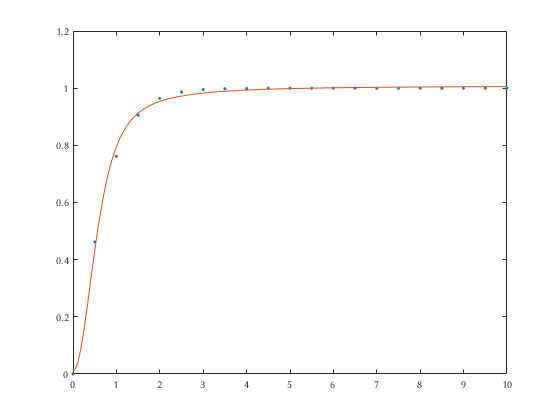

zfun = @(t) t.^2./(1+t.^2);
z = zfun(t);
V = z.^(0:3);
c = V\y;
% define f as an anonymous function
%  f(t) = c1 + c2*z(t) + c3*z(t)^2 + c4*z(t)^3
f = @(t) polyval(flip(c), zfun(t));

clf
plot(t,y,'.'), hold on
fplot(f, [0 10])

## Gram-Schmidt and Thin QR Factorization

### Example

Consider the subspace $S = \text{Sp}\{ \mathbf{a}_1, \mathbf{a}_2, \mathbf{a}_3 \} \subset \mathbb{R}^4$ where


$${\mathit{\mathbf{a}}}_1 =\left\lbrack \begin{array}{c}
1\\
1\\
1\\
1
\end{array}\right\rbrack ,\;{\mathit{\mathbf{a}}}_2 =\left\lbrack \begin{array}{c}
1\\
0\\
0\\
1
\end{array}\right\rbrack ,\;{\mathit{\mathbf{a}}}_3 =\left\lbrack \begin{array}{c}
4\\
2\\
-2\\
1
\end{array}\right\rbrack \ldotp$$


By the *Gram-Schmidt procedure*, we can obtain an orthonormal basis for $S$:

            $\mathbf{q}_1 = \frac{\mathbf{a}_1}{\Vert \mathbf{a}_1 \Vert_2} =$  $\frac{1}{2}\left\lbrack \begin{array}{c}
1\\
1\\
1\\
1
\end{array}\right\rbrack$ ,

            $\mathbf{q}_2 = \frac{\mathbf{w}_2}{\Vert \mathbf{w}_2 \Vert_2} =$$\frac{1}{2}\left\lbrack \begin{array}{c}
1\\
-1\\
-1\\
1
\end{array}\right\rbrack$,   where $\mathbf{w}_2 = \mathbf{a}_2 - (\mathbf{a}_2^T \mathbf{q}_1) \mathbf{q}_1$

 and 

            $\mathbf{q}_3 = \frac{\mathbf{w}_3}{\Vert \mathbf{w}_3 \Vert_2} =$$\frac{1}{5\sqrt{2}}\left\lbrack \begin{array}{c}
3\\
4\\
-4\\
-3
\end{array}\right\rbrack$,   where $\mathbf{w}_3 = \mathbf{a}_3 - (\mathbf{a}_3^T \mathbf{q}_1) \mathbf{q}_1 - (\mathbf{a}_3^T \mathbf{q}_2) \mathbf{q}_2$.

Moreover, the equations aboved can be rewritten as

            $\mathbf{a}_1 = \Vert \mathbf{a}_1 \Vert_2 \mathbf{q}_1$,

            $\mathbf{a}_2 = (\mathbf{a}_1^T \mathbf{q}_1) \mathbf{q}_1 + \Vert \mathbf{w}_2 \Vert_2 \mathbf{q}_2$,

            $\mathbf{a}_3 =  (\mathbf{a}_3^T \mathbf{q}_1) \mathbf{q}_1 + (\mathbf{a}_3^T \mathbf{q}_2) \mathbf{q}_2 + \Vert \mathbf{w}_3 \Vert_2 \mathbf{q}_3$.

In matrix form, they can be written as


$$\left\lbrack \begin{array}{ccc}
{\mathit{\mathbf{a}}}_1  & {\mathit{\mathbf{a}}}_2  & {\mathit{\mathbf{a}}}_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
{\mathbf{q}}_1  & {\mathbf{q}}_2  & {\mathbf{q}}_3 
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
{\left\|{\mathit{\mathbf{a}}}_1 \right\|}_2  & {\mathit{\mathbf{a}}}_2^T {\mathbf{q}}_1  & {\mathit{\mathbf{a}}}_3^T {\mathbf{q}}_1 \\
0 & {\left\|{\mathbf{w}}_1 \right\|}_2  & {\mathit{\mathbf{a}}}_3^T {\mathbf{q}}_2 \\
0 & 0 & {\left\|{\mathbf{w}}_3 \right\|}_2 
\end{array}\right\rbrack$$


or simply $A = \hat{Q} \hat{R}$ (thin QR factorization).

### Connection to QR Factorization

In MATLAB, we can easily calculate $Q$ and $R$ using `qr` function:

A = [1 1 1 1; 1 0 0 1; 4 2 -2 1]';
[Q, R] = qr(A, 0) % thin QR

Q =                       -0.5                       0.5         0.424264068711929
                      -0.5                      -0.5         0.565685424949238
                      -0.5                      -0.5        -0.565685424949238
                      -0.5                       0.5        -0.424264068711929


R =                         -2                        -1                      -2.5
                         0                         1                       2.5
                         0                         0          3.53553390593274


The second input argument '0' indicates that MATLAB is doing so-called the *thin QR factorization*. ($Q$ is a thin (tall) rectangular matrix.) Without it, it yields the *full* or *thick QR factorization:*

[Q, R] = qr(A)

Q =                       -0.5                       0.5         0.424264068711929        -0.565685424949238
                      -0.5                      -0.5         0.565685424949238         0.424264068711929
                      -0.5                      -0.5        -0.565685424949238        -0.424264068711929
                      -0.5                       0.5        -0.424264068711929         0.565685424949238


R =                         -2                        -1                      -2.5
                         0                         1                       2.5
                         0                         0          3.53553390593274
                         0                         0                         0


### Pseudocode

The general procedure of GS can be summarized as

$\begin{array}{rcl}
    \mathbf{q}_1 & = & \frac{\mathbf{a}_1}{r_{11}}, \\
    \mathbf{q}_2 & = & \frac{\mathbf{a}_2 - r_{12}\mathbf{q}_1}{r_{22}}, \\
    \mathbf{q}_3 & = & \frac{\mathbf{a}_3 - r_{13}\mathbf{q}_1 - r_{23}\mathbf{q}_2}{r_{33}}, \\
    & \;\;\vdots & \\
    \mathbf{q}_n & = & \frac{\mathbf{a}_n - \sum_{i=1}^{n-1}r_{in}\mathbf{q}_i}{r_{nn}},
  \end{array}$    where $r_{ij} =
  \cases{
    \mathbf{q}_i^{\rm T} \mathbf{a}_j, & if $i \neq j$ \cr
    \pm \left\Vert \mathbf{a}_j - \sum_{k=1}^{j-1}r_{kj} \mathbf{q}_k \right\Vert_{2}, & if $i =j$.
  }$

which can then be turned into a pseudocode (logics only, no MATLAB syntax) as shown below:

          Store the dimensions of $A$ as $m,n$

          Initialize $Q$ by making a copy of $A$. (This $Q$ will be overwritten below.)

          Initialize $R$ to be an $n\times n$ zero matrix. 

          for $j=1$ to $n$

                  for $i=1$ to $j-1$

                          
$$r_{ij} = \mathbf{q}_{i}^{\rm T} \mathbf{a}_{j}$$


                          
$$\mathbf{q}_j = \mathbf{q}_j - r_{ij} \mathbf{q}_i$$


                  
$$r_{jj} = \Vert \mathbf{q}_j \Vert_2$$


                  
$$\mathbf{q}_j = \mathbf{q}_j/r_{jj}$$


Even though the logic has been written using a nested for-loop, the inner loop can be vectorized resulting in a single loop for $j$. Either version will be okay for this homework. 